# Temperature modulation

everything currently set to temperature days starting with an increase in temperature to 30 deg C

## 9 hour tempday full light (no dark)

#### individual plots

kg(108) - Ginumbo

k_tempdayLLplotter(kg(108), 2, 0.5);

kg(109) - Mika

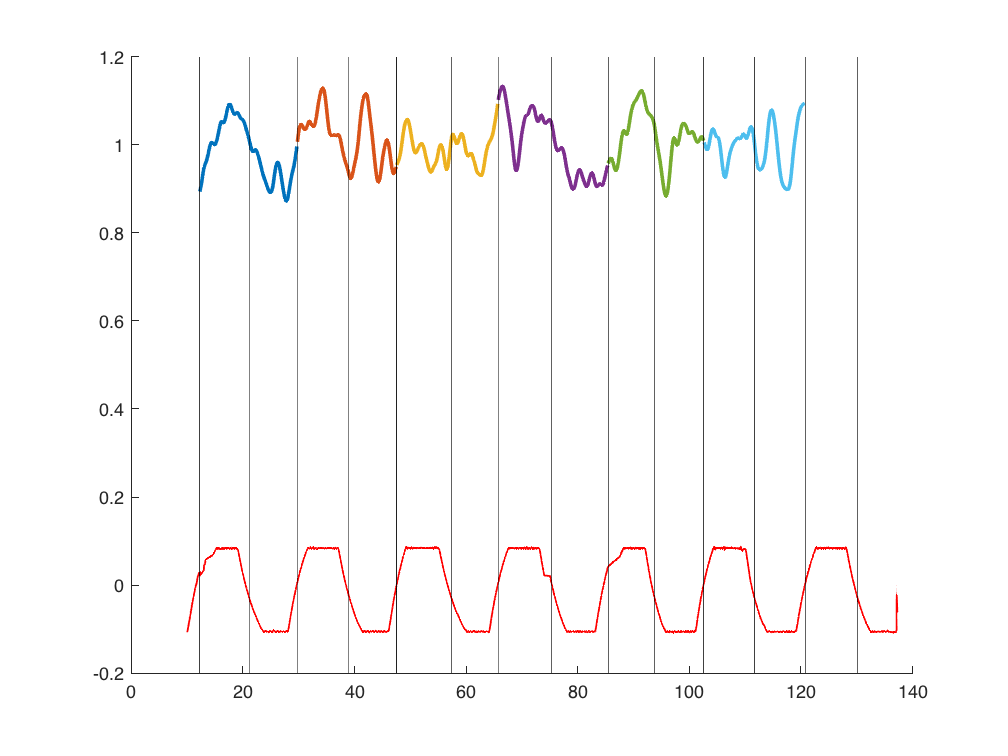

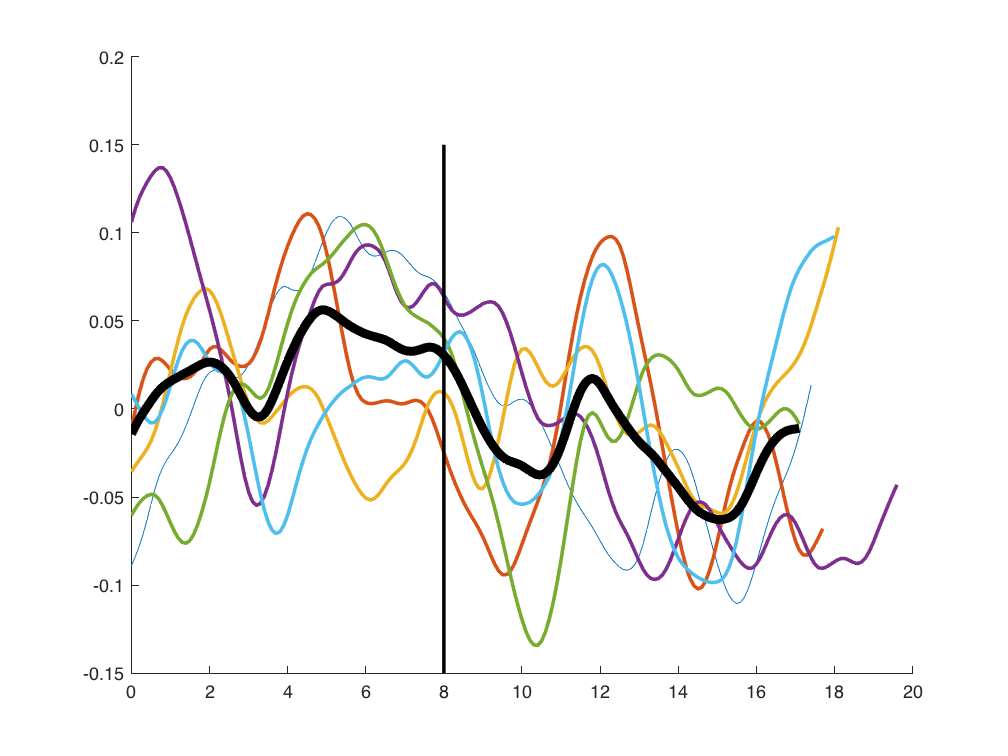

k_tempdayLLplotter(kg(109), 2, 0.5);

#### mean of means

kgtempidx = [108 109]; %109 is only good for ch2 so we look at ch2 for both

    for j = 1:length(kgtempidx)
        tday(j) = k_tempdayLL(kg(kgtempidx(j)), 2, 0.5);
    end

Unrecognized function or variable 'k_tempdayLL'.


k_tempdaymeanplotter(tday);

## 8 hour tempday; 48 hour LD

#### individual plots

kg(103) 

k_tempdayLDplotter(kg(103), 1, 0.5, -1);

kg(104) 

k_tempdayLDplotter(kg(104), 1, 0.5, 1);

kg(105) 

k_tempdayLDplotter(kg(105), 1, 0.5, -1);

#### mean of means

kgtempidx2 = [103 105]; 

    for j = 1:length(kgtempidx2)
        tday2(j) = k_tempdayLD(kg(kgtempidx2(j)), 2, 0.5, -1);
    end

    tday104 = k_tempdayLD(kg(104), 2, 0.5, 1);
    tday5 = [tday2 tday104];

k_tempdaymeanplotter(tday5);

## 6 hour tempday; DD with random light for feeding

#### individual plots

kg(50) 

k_tempdayLDplotter(kg(50), 1, 0.5, 1);

kg(51) 

k_tempdayLDplotter(kg(51), 1, 0.5, -1);

#### mean of means


    tday50 = k_tempdayLD(kg(50), 1, 0.5, 1);
    tday51 = k_tempdayLD(kg(51), 1, 0.5, -1);

    tday3 = [tday50 tday51];

k_tempdaymeanplotter(tday3);

## 14 hour tempday - not even close to symmetric; DD with random light for feeding

#### individual plots

kg(52) 

k_tempdayLDplotter(kg(52), 1, 0.5, 1);

kg(53) 

k_tempdayLDplotter(kg(104), 1, 0.5, 1);

#### mean of means

kgtempidx4 = [52 53]; 

    for j = 1:length(kgtempidx4)
        tday4(j) = k_tempdayLD(kg(kgtempidx4(j)), 2, 0.5, 1);
    end

k_tempdaymeanplotter(tday4);